r = randn(1,1000)';

% pendulum equations, no friction:
syms th(t) a
Dth = diff(th,t);
eqtn = diff(th,t,2) == -a*(th);
conds = [th(0) == pi/180*10, Dth(0) == 0];
sol(t) = simplify(dsolve(eqtn,conds));

g = 9.8; % m/s^2
l = 1; % m
m1 = 1; % kg
m2 = 2; % kg
a = 3*g/l*(m1/2 + m2)/(m1 + 3*m2);

sol(t) = simplify(subs(sol(t),sym('a'),a));

step = 0.01;
t = 0:step:10-step;

theta = double(sol(t))';
dsol = diff(sol);
dtheta = double(dsol(t))';
sigma = pi/18/5;
theta_rand = double(theta + r*sigma);
sigma_d = 0.1; % sqrt(m/s) 
dtheta_rand = double(dtheta + r*sigma_d);

xr = l*cos(theta_rand); x = l*cos(theta);
yr = l*sin(theta_rand); y = l*sin(theta);

% plot(xr,yr,'*',x,y)
% plot(t,theta_rand,'*',t,theta)

writematrix([theta_rand, dtheta_rand],"theta_dtheta_rand.csv")
writematrix([theta, dtheta],"theta_dtheta.csv")
writematrix(t',"t.csv")

## Practice discretization from ECE6555 HW4

A = [0 0 1 0; 0 0 0 1; zeros(2,4)];
B = [0 0; 0 0; 1 0; 0 1];
T = sym('T');
syms t;
expm(A*T)

expm(A*T)*B
int(expm(A*(T-t))*B*transpose(expm(A*(T-t))*B),sym('t'),[0,T])

## discretization of pendulum

% symbolically
syms a real
A = [0 1; a 0];
B = [0; 1];
syms T t;
simplify(expm(A*(T-t)))

$$ans = \left(\begin{array}{cc} \cosh\left(\sqrt{a}\,\left(T-t\right)\right) & \frac{\sinh\left(\sqrt{a}\,\left(T-t\right)\right)}{\sqrt{a}}\\ \sqrt{a}\,\sinh\left(\sqrt{a}\,\left(T-t\right)\right) & \cosh\left(\sqrt{a}\,\left(T-t\right)\right) \end{array}\right)$$

simplify(expm(A*(T-t))*transpose(expm(A*(T-t))))

$$ans = \begin{array}{l} \left(\begin{array}{cc} {\cosh\left(\sigma_{2}\right)}^{2}+\frac{{\sinh\left(\sigma_{2}\right)}^{2}}{a} & \sigma_{1}\\ \sigma_{1} & {\left(\frac{\sqrt{a}\,{\mathrm{e}}^{\sigma_{2}}}{2}-\frac{\sqrt{a}\,{\mathrm{e}}^{-\sigma_{2}}}{2}\right)}^{2}+{\left(\frac{{\mathrm{e}}^{\sigma_{2}}}{2}+\frac{{\mathrm{e}}^{-\sigma_{2}}}{2}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sinh\left(2\,\sqrt{a}\,\left(T-t\right)\right)\,\left(2\,a+2\right)}{4\,\sqrt{a}}\\ \sigma_{2}=\sqrt{a}\,\left(T-t\right) \end{array}$$

simplify(int(expm(A*(T-t))*B*transpose(expm(A*(T-t))*B),sym('t'),[0,T]))

$$ans = \left(\begin{array}{cc} \frac{\sinh\left(2\,T\,\sqrt{a}\right)}{4\,a^{3/2}}-\frac{T}{2\,a} & \frac{{\sinh\left(T\,\sqrt{a}\right)}^{2}}{2\,a}\\ \frac{{\sinh\left(T\,\sqrt{a}\right)}^{2}}{2\,a} & \frac{T}{2}+\frac{\sinh\left(2\,T\,\sqrt{a}\right)}{4\,\sqrt{a}} \end{array}\right)$$


% what does it look like with unit parameters? linearized around theta = 0
A = [0 1; -1 0];
B = [0; 1];
syms T t real
simplify(expm(A*(T-t)))

$$ans = \left(\begin{array}{cc} \cos\left(T-t\right) & \sin\left(T-t\right)\\ -\sin\left(T-t\right) & \cos\left(T-t\right) \end{array}\right)$$

simplify(expm(A*(T-t))*transpose(expm(A*(T-t))))

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

simplify(int(expm(A*(T-t))*B*transpose(expm(A*(T-t))*B),sym('t'),[0,T]))

$$ans = \left(\begin{array}{cc} \frac{T}{2}-\frac{\sin\left(2\,T\right)}{4} & \frac{{\sin\left(T\right)}^{2}}{2}\\ \frac{{\sin\left(T\right)}^{2}}{2} & \frac{T}{2}+\frac{\sin\left(2\,T\right)}{4} \end{array}\right)$$


% with real numbers:
a = -3*g*(m1/2 + m2)/(l*(m1 + 3*m2));
qf = 3/(l^2*(m1 + 3*m2));
A = [0 1; a 0];
B = [0; 1];
syms T t;
N = 0.1; % N-m, power of process noise
q = qf^2*N;
Qk = simplify(q*int(expm(A*(T-t))*B*transpose(expm(A*(T-t))*B),sym('t'),[0,T]))

$$Qk = \begin{array}{l} \left(\begin{array}{cc} \frac{3\,T}{3430}-\frac{\sqrt{42}\,\sin\left(\sqrt{42}\,T\right)}{48020} & \sigma_{1}\\ \sigma_{1} & \frac{9\,T}{980}+\frac{3\,\sqrt{42}\,\sin\left(\sqrt{42}\,T\right)}{13720} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{3\,{\mathrm{e}}^{-\sqrt{42}\,T\,\mathrm{i}}\,{\left({\mathrm{e}}^{\sqrt{42}\,T\,\mathrm{i}}-1\right)}^{2}}{13720} \end{array}$$

Qk_real = real(double(subs(Qk,T,step)))

Qk_real = 1.0e-03 *

   0.000006121163394   0.000918045963364
   0.000918045963364   0.183609197172119


## Discrete Time SS model

F = double(expm(A*step))

F =    0.999475045935892   0.009998250091873
  -0.104981625964663   0.999475045935892


H = [1 0]

H =      1     0


G = eye(2)

G =      1     0
     0     1



rank(obsv(F,H)) % system is observable. 

ans =      2


## Plot filtered data

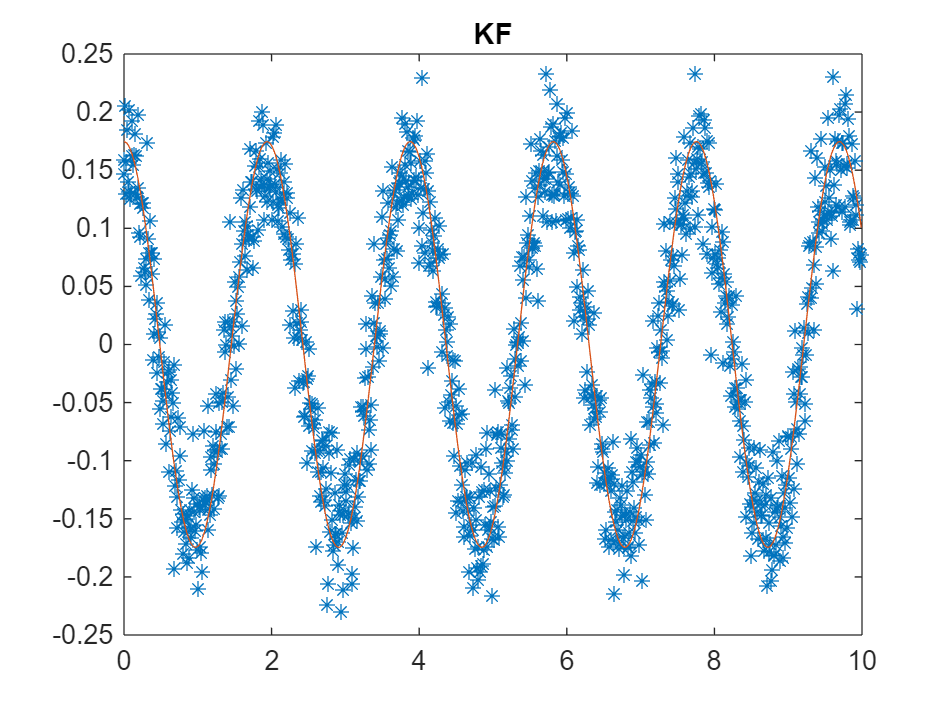

filtered = readmatrix("filtered_data.csv");
plot(t',filtered(:,1),'*',t',theta); title('KF');

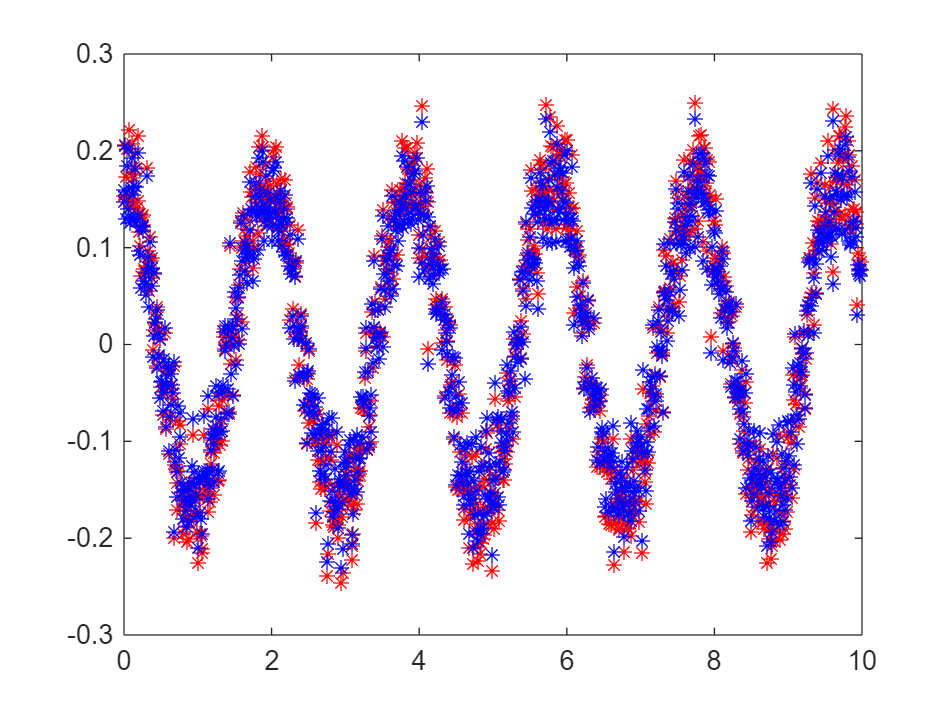

figure;
plot(t',theta_rand,'r*',t',filtered(:,1),'b*');